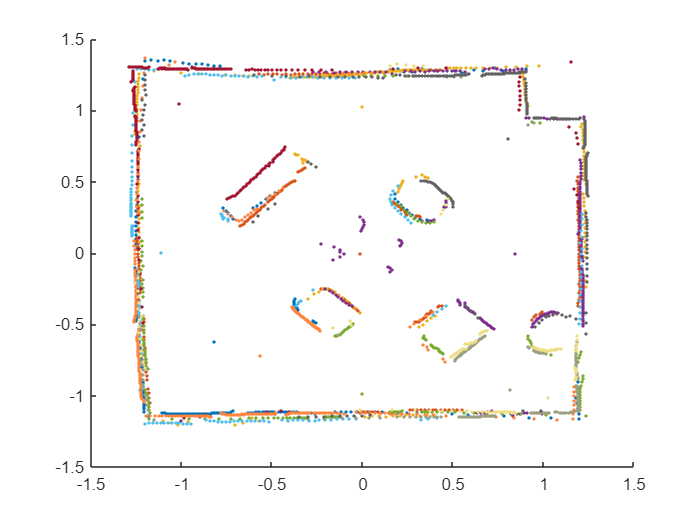

clear

load data/bottomleftblue.mat
load data/origin.mat
load data/topmid.mat
load data/rightmid.mat
load data/bottommid.mat
load data/midleft.mat
load data/topleft.mat
load data/bluebucket.mat
load data/bottomright.mat
load data/topright.mat
load data/bottommostright.mat

clf

bottomleftblue = globalframe(bottomleftblue.ranges,bottomleftblue.thetasInRadians,0.68,-0.811, -0.613);
origin = globalframe(origin.ranges,origin.thetasInRadians,0,0, 0);
topmid = globalframe(topmid.ranges,topmid.thetasInRadians,-1.58,0, 1.016);
rightmid = globalframe(rightmid.ranges,rightmid.thetasInRadians,-3.17,0.8366, 0);
bottommid = globalframe(bottommid.ranges,bottommid.thetasInRadians,1.53,0, -0.9715);
midleft = globalframe(midleft.ranges,midleft.thetasInRadians,-0.02,-1.1, 0);
topleft = globalframe(topleft.ranges,topleft.thetasInRadians,-0.895,-1.005, 1.041);
bluebucket = globalframe(bluebucket.ranges,bluebucket.thetasInRadians,0.695, -0.558, -0.713);
bottomright = globalframe(bottomright.ranges,bottomright.thetasInRadians,2.13, 0.813, -0.949);
topright = globalframe(topright.ranges,topright.thetasInRadians,-2.35,0.802, 0.797);
bottommostright = globalframe(bottommostright.ranges,bottommostright.thetasInRadians,1.58,1.026, -1.006);

hold on

all_points = [bottomleftblue origin topmid rightmid bottommid midleft topleft bluebucket bottomright topright bottommostright];
%all_points = [bottommostright];
plot(bottomleftblue(1,:),bottomleftblue(2,:),".","Color","#0072BD")
hold on
plot(origin(1,:),origin(2,:),".","Color","#D95319")
plot(topmid(1,:),topmid(2,:),".","Color","#EDB120")
plot(rightmid(1,:),rightmid(2,:),".","Color","#7E2F8E")
plot(bottommid(1,:),bottommid(2,:),".","Color","#77AC30")
plot(midleft(1,:),midleft(2,:),".","Color","#4DBEEE")
plot(topleft(1,:),topleft(2,:),".","Color","#A2142F")
plot(bluebucket(1,:),bluebucket(2,:),".","Color","#ff8440")
plot(bottomright(1,:),bottomright(2,:),".","Color","#9c9e7f")
plot(topright(1,:),topright(2,:),".","Color","#626262")
plot(bottommostright(1,:),bottommostright(2,:),".","Color","#eedd82")


save("finalgaunlet_map.mat","all_points")

function globalrange = globalframe(range,theta,angle,x,y)
 globalrange=[range.*cos(theta+angle)-0.01*cos(angle)+x;range.*sin(theta+angle)-0.01*sin(angle)+y];
end